clear;close all;clc;
hand1 = imread('Hand1.jpg');% reference/fixed
hand2 = imread('Hand2.jpg');% template/moving

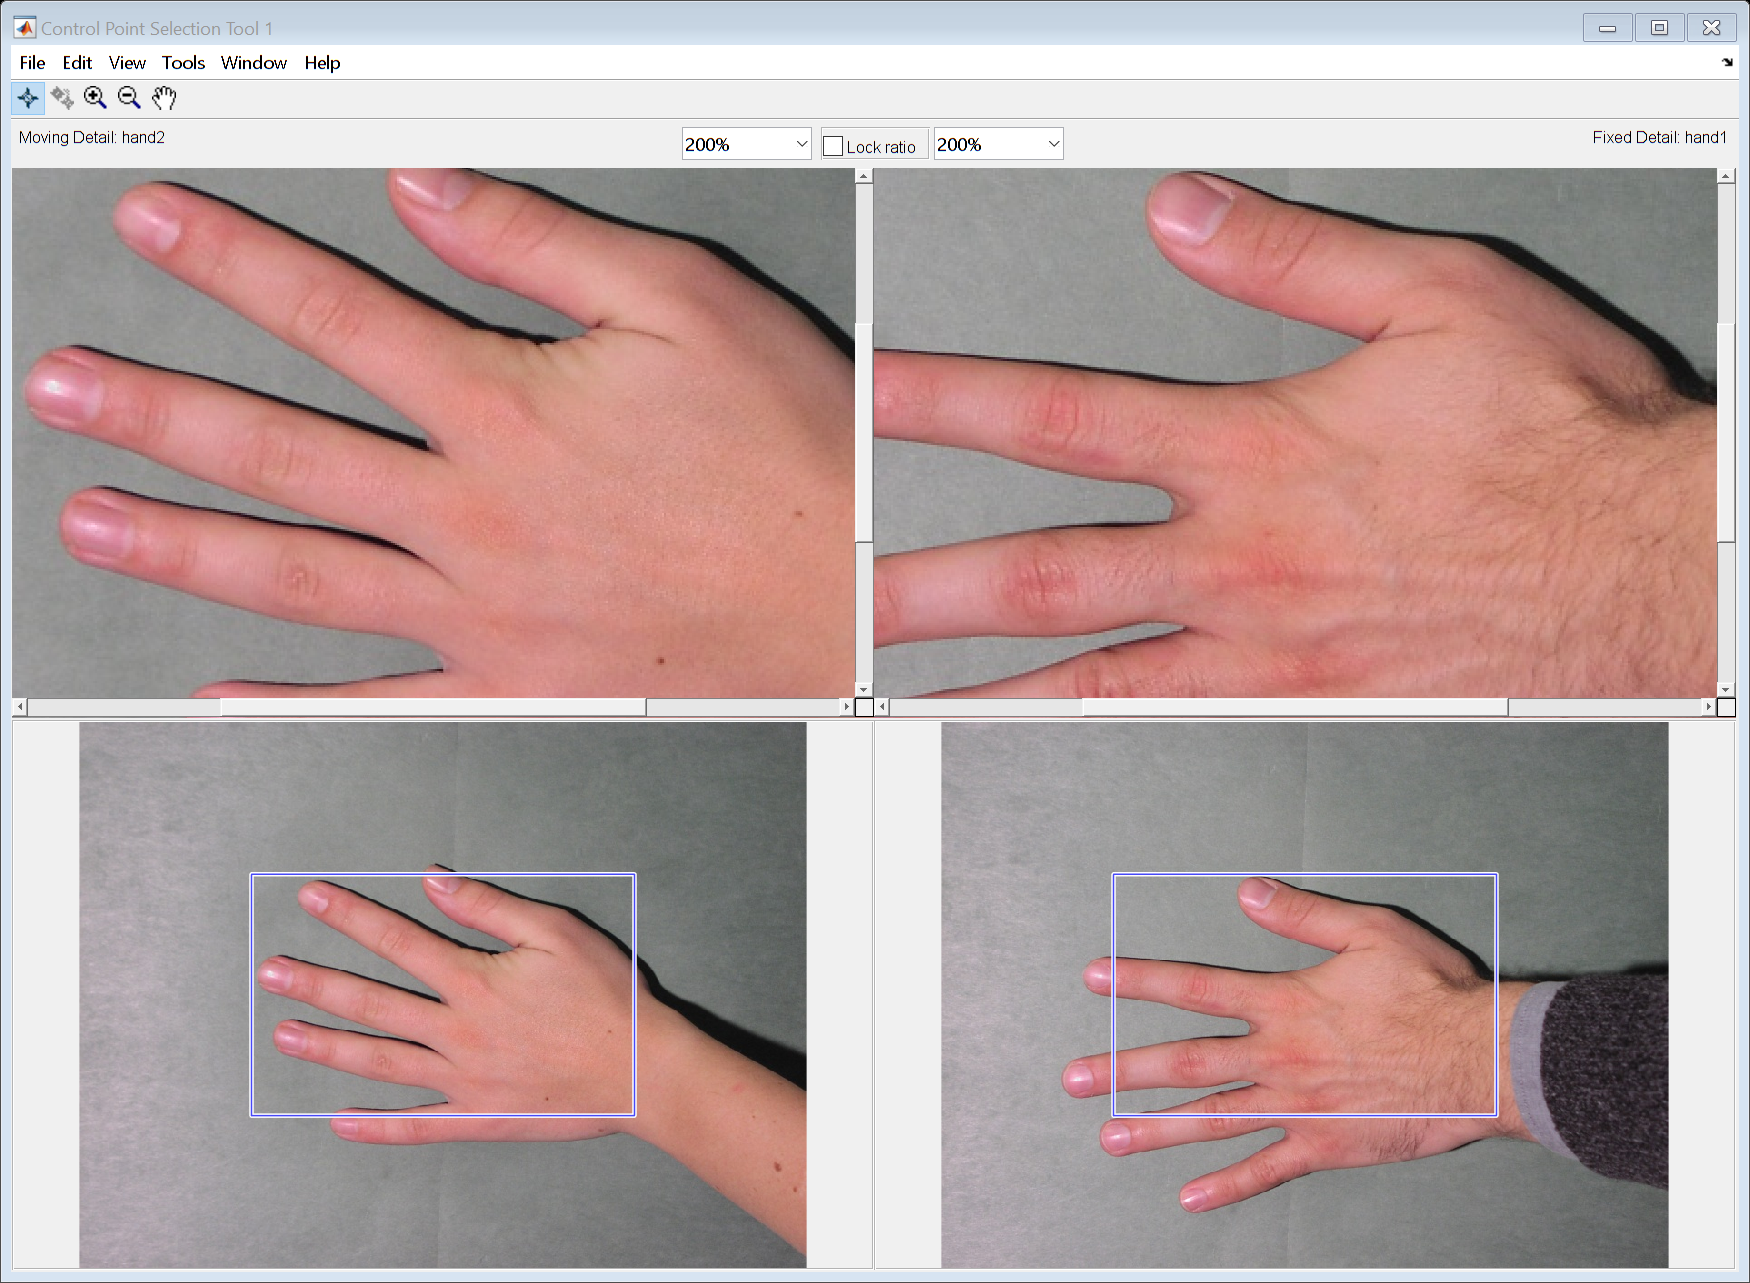

% ex1
cpselect(hand2,hand1);

save('fixedPoints.mat','fixedPoints');

Error using save
Variable 'fixedPoints' not found.

save('movingPoints.mat','movingPoints');

% ex2
figure;
plot(fixedPoints(:,1), fixedPoints(:,2), 'b*-', ...
movingPoints(:,1), movingPoints(:,2), 'r*-');
legend('Hand 1 - The fixed image', 'Hand 2 - The moving image');
axis ij; % This reverses the direction of the axis

F = sum([(fixedPoints(:,1)-movingPoints(:,1)).^2+(fixedPoints(:,2)-movingPoints(:,2)).^2]);

% ex3
ex = fixedPoints(:,1) - movingPoints(:,1);
errorX = ex' * ex;
ey = fixedPoints(:,2) - movingPoints(:,2);
errorY = ey' * ey;
F = errorX + errorY;

% ex4
fixed_COM = [mean(fixedPoints(:,1)),mean(fixedPoints(:,2))];
moving_COM = [mean(movingPoints(:,1)),mean(movingPoints(:,2))];

% ex5
fixed_trans = [fixedPoints(:,1) - fixed_COM(1) ...
fixedPoints(:,2) - fixed_COM(2)];
moving_trans = [movingPoints(:,1) - moving_COM(1) ...
movingPoints(:,2) - moving_COM(2)];
figure;
plot(fixed_trans(:,1), fixed_trans(:,2), 'b*-', ...
moving_trans(:,1), moving_trans(:,2), 'r*-');
legend('Hand 1 - The fixed image', 'Hand 2 - The moving image');
axis ij; % This reverses the direction of the axis

% ex6
mytform = cp2tform(movingPoints, fixedPoints,'linear conformal');

% ex7
forward = tformfwd(mytform,movingPoints);
figure;
plot(fixed_trans(:,1), fixed_trans(:,2), 'b*-', ...
forward(:,1), forward(:,2), 'r*-');
legend('Hand 1 - The fixed image', 'Hand 2 - The transformed moving image');
axis ij; % This reverses the direction of the axis

% ex8
F1 = sum([(fixedPoints(:,1)-forward(:,1)).^2+(fixedPoints(:,2)-forward(:,2)).^2]);

% ex9
hand2t = imtransform(hand2, mytform);
imshow(hand2t);
figure;
imshow(hand1);

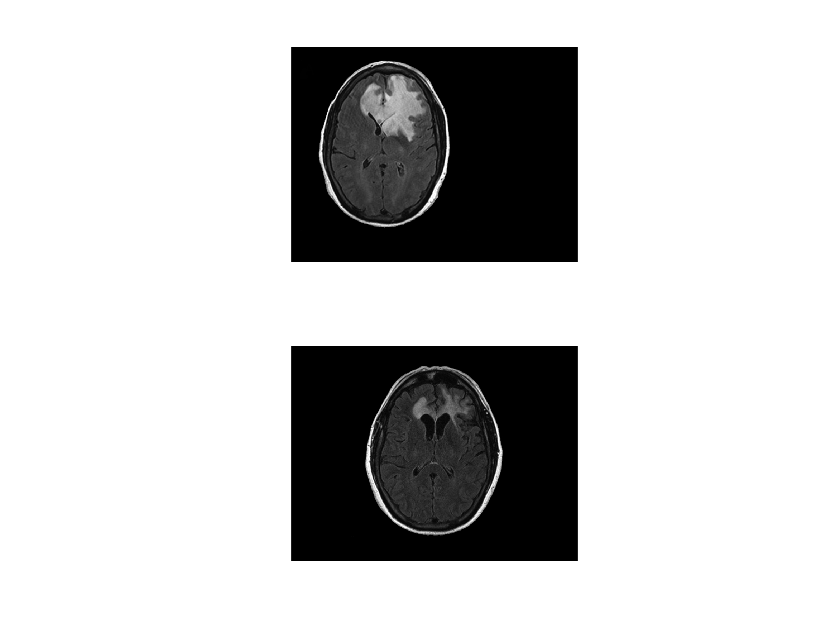

% ex10
clear;close all;clc;
bt1 = imread('BT1.png');% reference/fixed
bt2 = imread('BT2.png');% template/moving
figure;
subplot(2,1,1)
imshow(bt1);
subplot(2,1,2)
imshow(bt2)

% ex11
cpselect(bt2,bt1);
save('BT1Points.mat',"fixedPoints");
save('BT2Points.mat',"movingPoints");

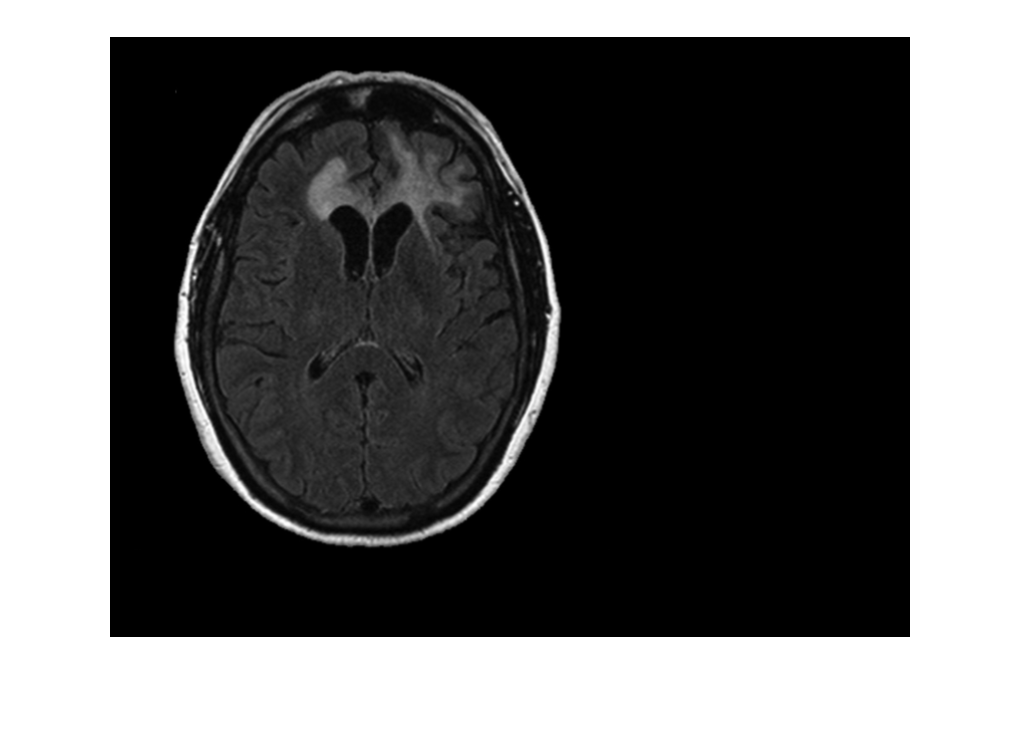

% ex12
load('BT1Points.mat');
load('BT2Points.mat');
mytform = cp2tform(movingPoints, fixedPoints,'linear conformal');
I = imtransform(bt2, mytform);
[Width Height] = size(bt1(:,:,1));
TI = imtransform(I, mytform, 'XData',[1 Height], 'YData',[1 Width]);
imshow(TI);

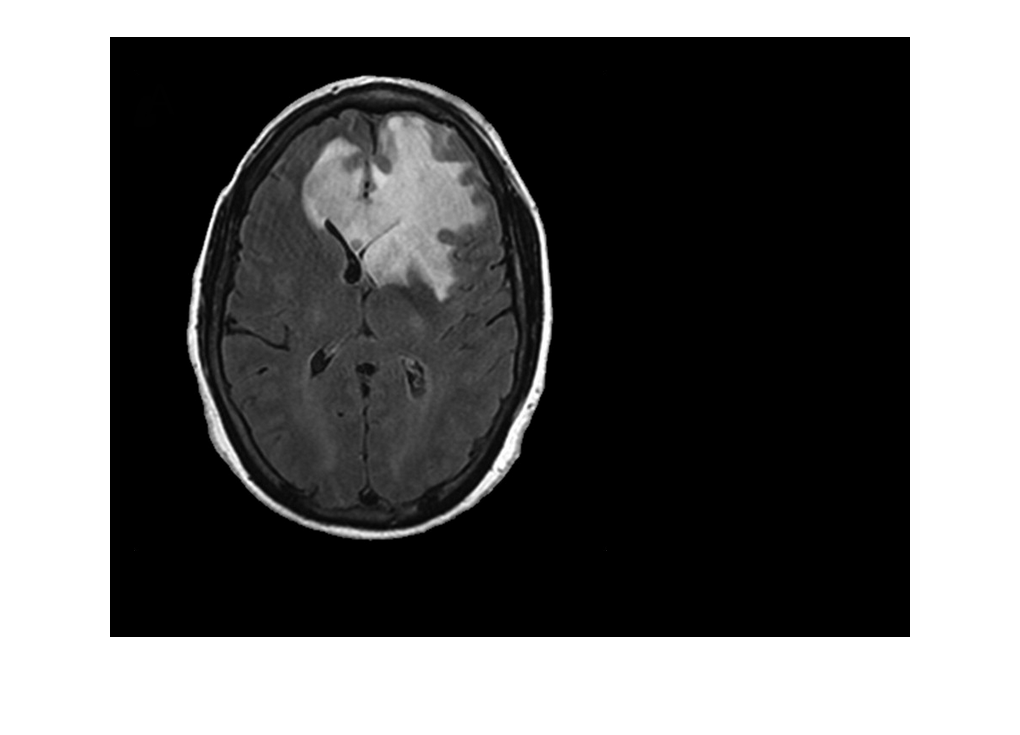

figure;
imshow(bt1);

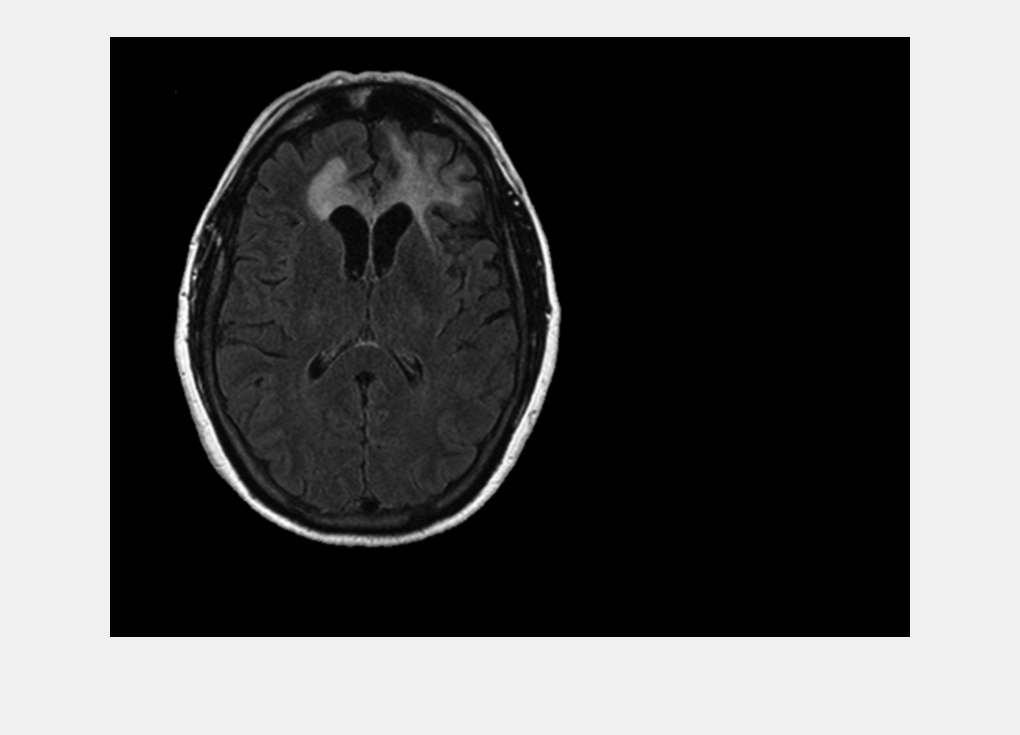

% ex13
I1 = roipoly(TI);

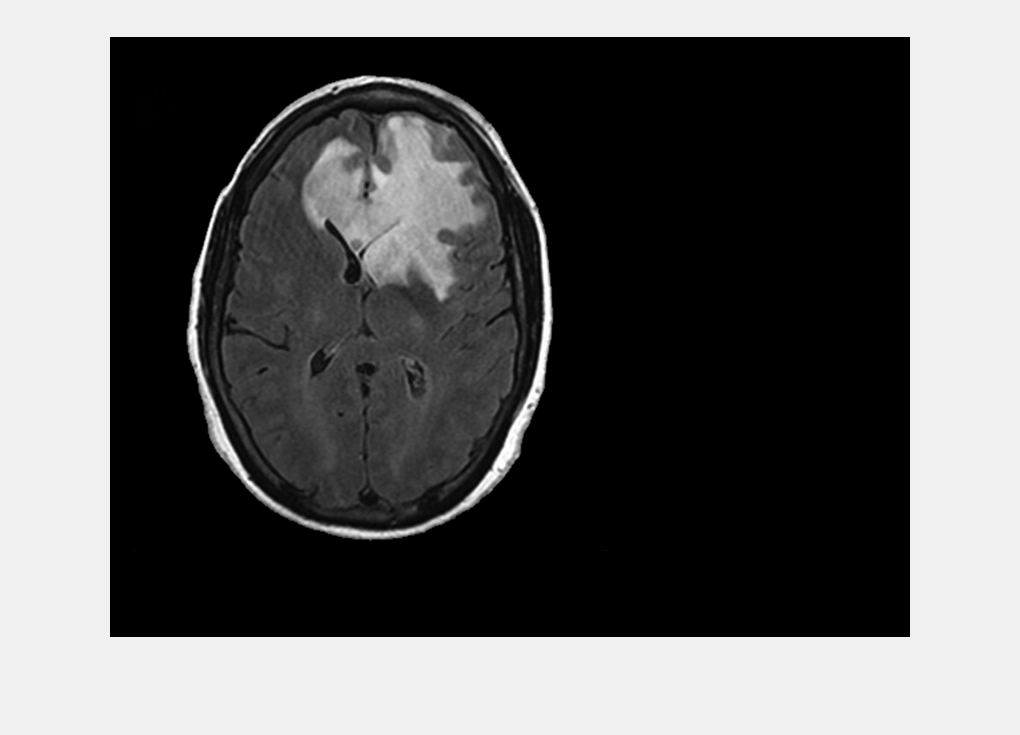

I2 = roipoly(bt1);

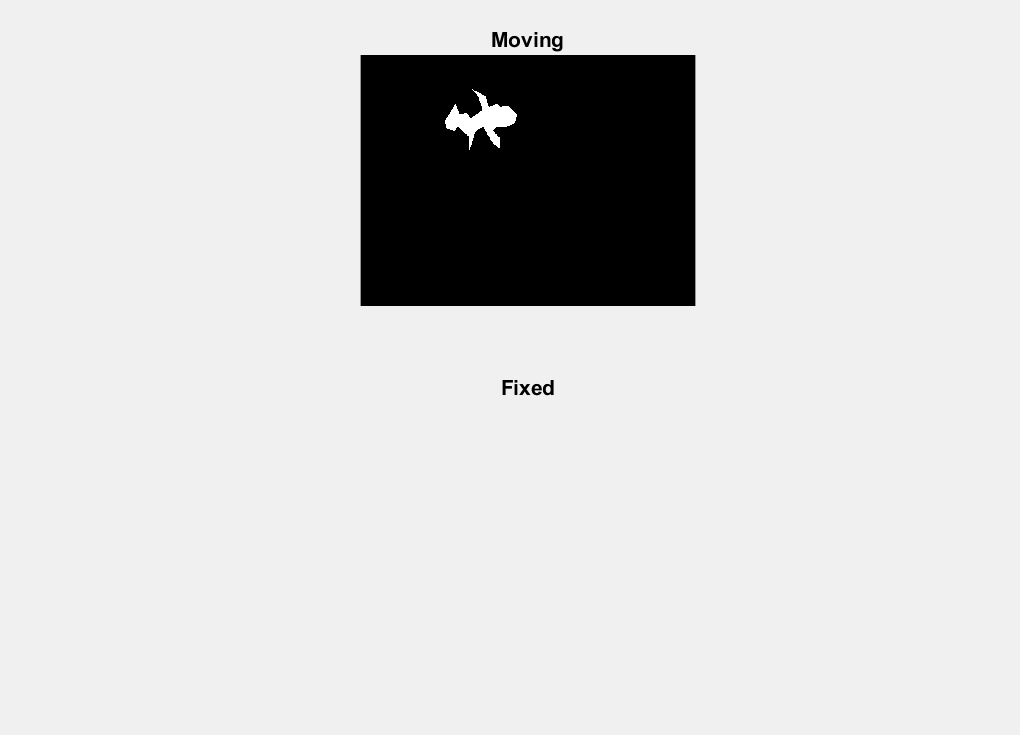

save BT1_annot.png I2;
save BT2_annot.png I1;
subplot(2,1,1);
imshow(I1);
title('Moving')
subplot(2,1,2);
imshow(I2);
title('Fixed');

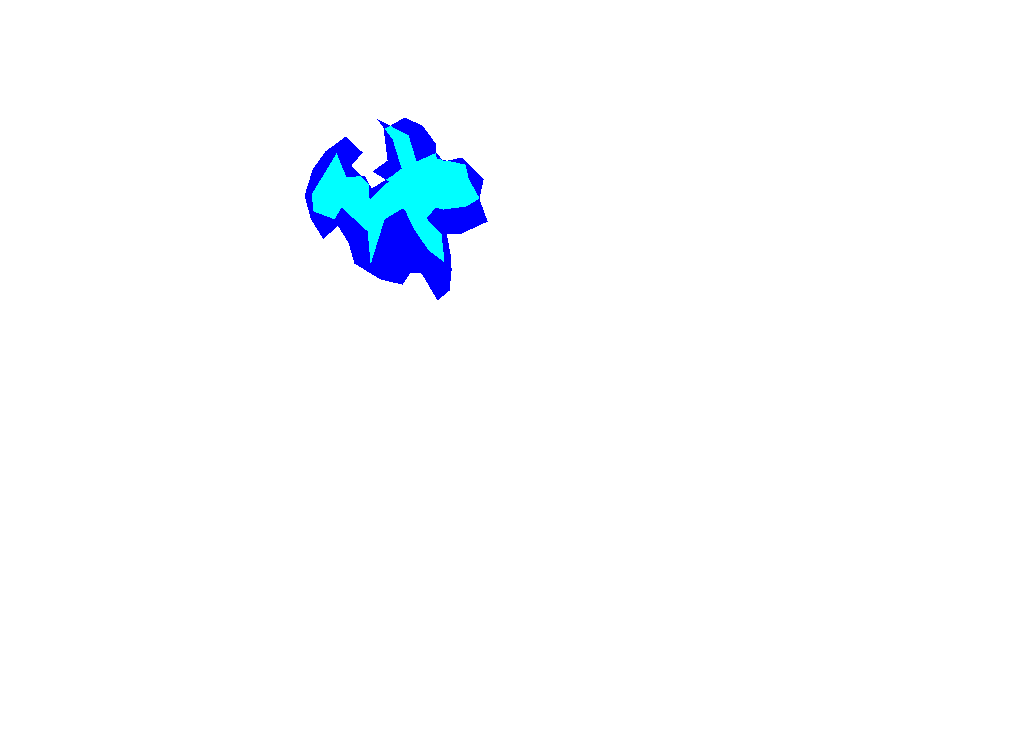

% ex14
I = I1+I2;
II = label2rgb(I);
imshow(II);

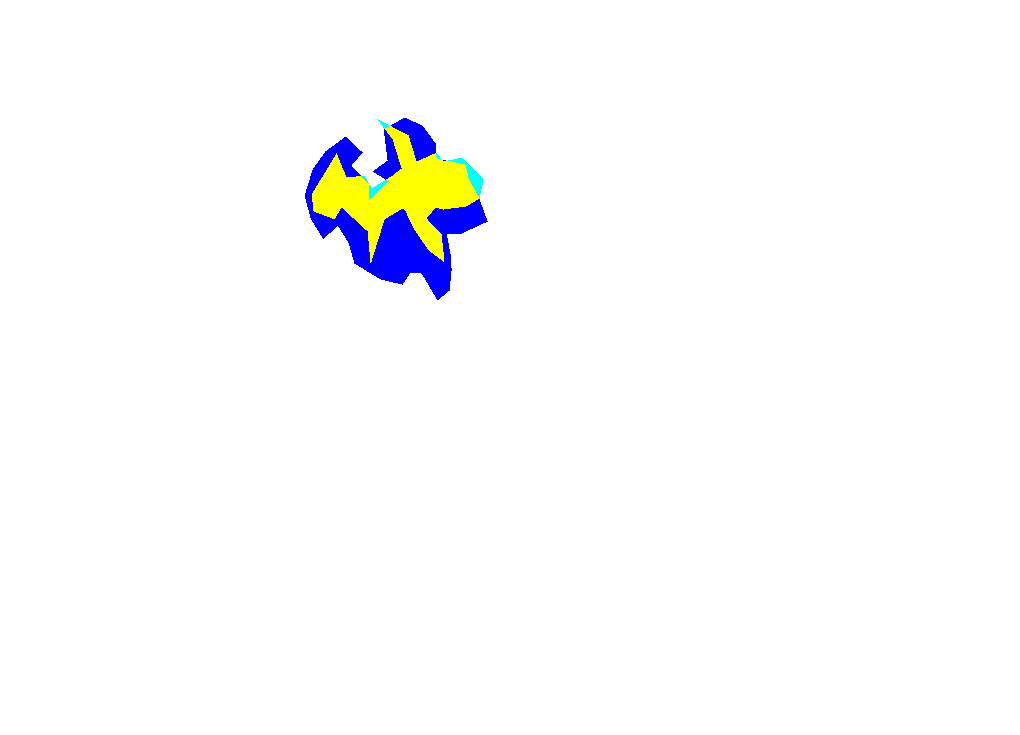

I = 2*I1+I2;
II = label2rgb(I);
imshow(II);

% ex15
A = sum(sum(I2))-sum(sum(I1));